## Exercise 1

#### 1. Write a function that produces a random network with N nodes and A arrows.

Functions need to be put in a separate script.

So here the function is just reported. It is better that the function and the script containing it have the same name

2 objects need to be created for this task:

**> Interaction tables:**

2 column tables where on the the first one you put where the edges start (FROM), while in the other where they end (TO)

In case of undirected graphs, putting 1 to 2 would also represent the opposite

**> Adjacency matrix:**

matrix having all the empty cells filled with 0, while a number matching where .................................

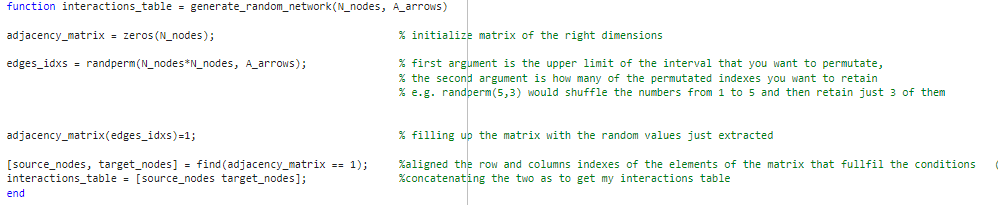

#### **2. Count the number of self-arrows in the network of E.coli (ecoli.xls). Generate 100 random networks with the same number of nodes and arrows **as the real network. **What is the mean and standard deviation of the number of self-arrows in the random networks? How does it compare to the real network value?**

Loading the data:

ecoli_table = readtable('ecoli.xlsx','Sheet','GENE');     % reads the specific sheet from the excel file and creates a "table" dataobject
ecoli_table = table2cell(ecoli_table);                    % converting into a "cell" dataobject (switching to a cell-matrix representation)
ecoli_interactions_table = ecoli_table(:,[2,4]);          % storing only the interaction table with the IDs

Counting the number of self arrows:

nself_arrows_ecoli = sum(strcmp(ecoli_interactions_table(:,1), ...         %compare the strings elementwise (positionwise) obtain an array with 1 in correspondance to strings that were equal
                                ecoli_interactions_table(:,2)));

generating 100 random network:

rng(1)                                                      % just fixing a seed so that we all have the same result
n_of_networks = 100;
A_arrows = size(ecoli_interactions_table,1);
N_nodes = length(unique(ecoli_interactions_table));   

nself_arrows_random = zeros(1,n_of_networks);
for i = 1:n_of_networks
    interactions_table = generate_random_network(N_nodes,A_arrows);
    nself_arrows_random(i) = sum(interactions_table(:,1) == interactions_table(:,2));    % no strings here but rather numbers so we can just use == to compare rather than compstr
end

Comparing the real and random networks

disp(nself_arrows_ecoli)                 

   146



disp(mean(nself_arrows_random))         

    2.9500



disp(std(nself_arrows_random))  

    1.6840



146 autoregulatory motifs in the Ecoli network versus an average of 3 in the random ones, so it is evident that autoregulation is a motif in our network and it happens a lot more than it would occur in a random one

#### **3. Repeat point 2, this time considering the number of FFLs (Feed-forward loops).**

defining a function to number the FFLs

% function n_of_FFLs = find_FFLs(interactions_table)
% 
% graph = digraph(interactions_table(:,1), interactions_table(:,2));           %produces an object of type graph provided the ______
% adj_matrix = adjacency(graph);
% 
% FFLs_list = {};
% 
% for i = 1:size(adj_matrix,1)
%     target_nodes = find(adj_matrix(i,:)==1);
%     target_nodes = target_nodes(target_nodes ~= i);                          %removes the self loop if present
% 
%     % finding the targets of each target node
%     for j = 1:length(target_nodes)
%         next_target_nodes = find(adj_matrix(j,:)==1);
%         next_target_nodes = next_target_nodes(next_target_nodes ~=j);
% 
%         % finding which out of these "targets of targets" are also targets of i
%         for k = 1:length(next_taget_nodes)
%             if adj_matrix(i,k) == 1
%                 FFLs_list = [FFLs_list[i j k]];                             % appending the found FFL in the list
%             end
%         end
%     end
% end
% n_of_FFLs = length(FFLs_list);
% end

counting the FFLs:

n_FFLs_ecoli = find_FFLs(ecoli_interactions_table)

n_FFLs_ecoli = 2452

generating 50 random networks:

rng(1)                                                  % just fixing a seed so that we all have the same result
n_of_networks = 50;
A_arrows = size(ecoli_interactions_table,1);
N_nodes = length(unique(ecoli_interactions_table));   

n_FFLs_random = zeros(1,n_of_networks);
for i = 1:n_of_networks
    interactions_table = generate_random_network(N_nodes,A_arrows);  
    n_FFLs_random(i) = find_FFLs(interactions_table);
end

Comparing the real and random networks

disp(n_FFLs_ecoli)                 

        2452



disp(mean(n_FFLs_random))         

   26.4400



disp(std(n_FFLs_random)) 

    4.9576



again we can see that the FFL is a motif in our network and is much more prevalent than in a random network

## Exercise 2

Fixing β and K, plot the following input functions

K = 0.8;
beta = 2.5

beta = 2.5000

steepnesses = 1:4;

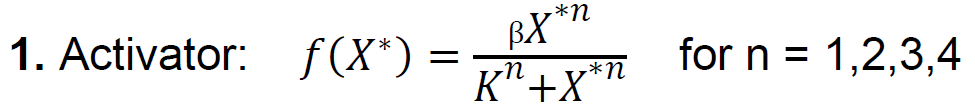

setting up the function:

    

plotting all together:

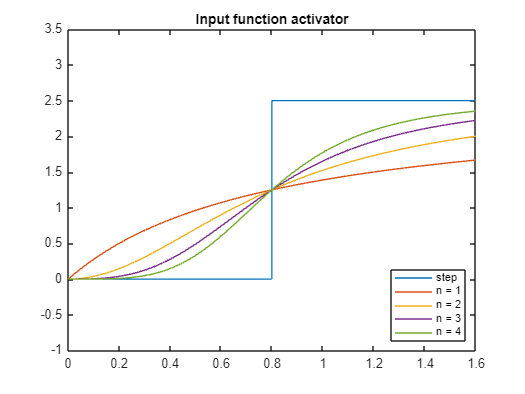

figure

x_max = 2*K;
plot([0, K, K, x_max],[0,0,beta,beta],'DisplayName','step')         %plotting the step function as a reference

ylim([-1 beta+1])    
legend('Location','se')
title('Input function activator')

hold on
X = linspace(0,x_max,100);
for i=1:length(steepnesses)
    n = steepnesses(i);
    plot(X,f_activator(X,beta,K,n), 'DisplayName',['n = ' num2str(n)])
end

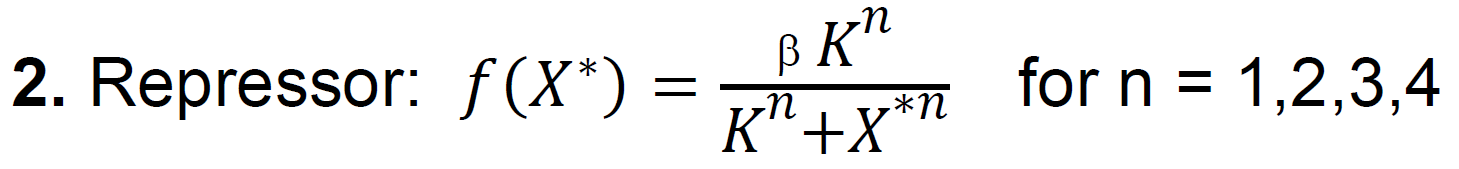

setting up the function:

    

plotting all together:

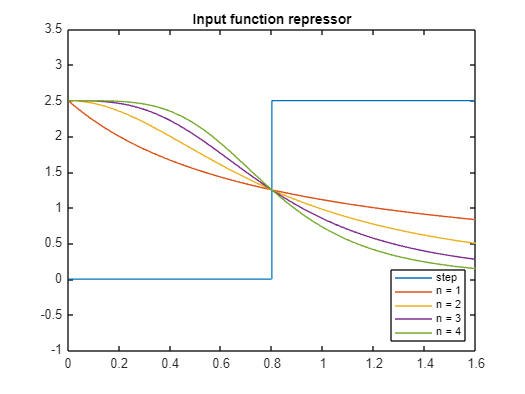

figure
% plot step function as reference
x_max = 2*K;
plot([0, K, K,x_max],[0,0,beta,beta],'DisplayName','step')

ylim([-1 beta+1])
legend('Location','se')
title('Input function repressor')

hold on
X = linspace(0,x_max,100);
for i=1:length(steepnesses)
    n = steepnesses(i);
    plot(X,f_repressor(X,beta,K,n),'DisplayName',['n = ' num2str(n)])
end